## ESERCITAZIONE

Consideriamo il sistema meccanico 

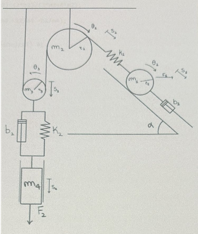

Nell'ipotesi in cui la massa m1 rotoli senza scivolare, il sistema presenterà 3 gradi di libertà. Scegliendo come origine del nostro riferimento quello delle molle elongate sotto l'azione della forza peso, il modello matematico del sistema risulterà:


$$\dot x(t) =A x(t)+Bu(t) 
$$



$$y(t)=x(t)
$$


con 


$$\begin{array}{l}
{\;x}_1 =s_{1\;} \\
x_2 ={\dot{\;s\;} }_1 
\end{array}$$
         
$$\begin{array}{l}
{\;x}_3 =s_{3\;} \\
x_4 ={\dot{\;s\;} }_3 
\end{array}$$
         
$$\begin{array}{l}
{\;x}_5 ={s_{\;} }_4 \\
x_6 ={\dot{\;s\;} }_4 
\end{array}$$
 

e 


$$A=\left\lbrack \begin{array}{cccccc}
0 & 1 & 0 & 0 & 0 & 0\\
-\frac{1}{J_1 }k_1  & -\frac{1}{J_1 }b_1  & -\frac{2}{J_1 }k_1  & 0 & 0 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
-2\frac{k_1 }{J_2 } & 0 & -\frac{\left(4k_{1\;} +k_2 \right)}{J_2 } & -\frac{b_2 }{J_2 } & -\frac{k_2 }{J_2 } & -\frac{b_2 }{J_2 }\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & \frac{k_2 }{m_4 } & \frac{b_2 }{m_4 } & -\frac{k_2 }{m_4 } & -\frac{b_2 }{m_4 }
\end{array}\right\rbrack$$



$$B=\left\lbrack \begin{array}{cc}
0 & 0\\
\frac{\cos \left(\alpha \right)}{J_1 } & 0\\
0 & 0\\
0 & 0\\
0 & 0\\
0 & \frac{1}{m_4 }
\end{array}\right\rbrack$$


con $J_1 =\frac{3}{2}m_{1\;}$ e  $J_{2\;} =\left(1+\frac{R_3 }{2R_2 }\right)m_3 +2m_2$.

Considerando i seguenti valori per le costanti del sistema:

k1=1;  k2=0.5;   k3=1.2;    b1=0.4;   b2=0.4;    b3=0.6;    m1=0.6;   m2=1.5;     m3=0.75;    m4=0.1;   R2=R3=0.1; alpha=30;

progettare le seguente strategie di controllo e verificarle in ambiente simulink:

1) Retroazione di stato con assegnamento degli autovalori e compensazione del guadagno al fine di controllore la posizione delle masse s1 ed s4 in modo da avere tempo di assestamento di 10s e assenza di sovraelongazione 

2) Retroazione di stato con assegnamento degli autovalori con azione integrale al fine di controllore la posizione delle masse  s1 ed s4 in modo da avere tempo di assestamento di 10s e assenza di sovraelongazione

3) Controllo LQ con compensazione del guadagno al fine di controllore la posizione delle masse s1 ed s4

4) Controllo  LQ con azione integrale sul sistema aumentato al fine di controllore la posizione delle masse  s1 ed s4

5) Controllo LQG con filtro di Kalman al fine di controllore la posizione delle masse  s1 ed s4

6) Controllo H-infinito al fine di controllore la posizione delle masse  s1 ed s4

## SOLUZIONE

clear all
close all
clc


## MODELLO DEL SISTEMA



% VARIABILI DEL SISTEMA

k1=1;  
k2=0.5;   
k3=1.2;    
b1=0.4;   
b2=0.4;    
b3=0.6;    
m1=0.6;   
m2=1.5;     
m3=0.75;    
m4=0.1;   
R2=0.1;
R3=0.1;
alpha=30*pi/180;

% MATRICI DINAMICHE

J1=3/2*m1;
J2=(1+R3/(2*R2))*m3+2*m2;

A=[    0        1         0            0       0           0;
    -k1/J1    -b1/J1   -2*k1/J1        0       0           0;
       0        0         0            1       0           0;
    -2*k1/J2    0     -(4*k1+k2)/J2  -b2/J2  -k2/J2    -b2/J2;
       0        0         0            0       0           1;
       0        0       k2/m4        b2/m4    -k2/m4     -b2/m4];


  
B=zeros(6,1);

B(2,1)=cos(alpha)/J1;
B(6,2)=1/m4;

C=eye(6);

%C=[1 0 0 0 0 0; 
%   0 0 0 0 1 0];
D=zeros(6,2);
sys=ss(A,B,C,D);

## 3) Controllo LQ con compensazione del guadagno

% Scelta delle matrici di peso

Qtilde=1;
Q=C'*Qtilde*C;
R=eye(2);

% problema LQ

[K,P,Poles] = lqr(sys,Q,R)

K =     0.8335    1.2500   -0.2730   -1.0405    0.0333    0.0118
    0.2041    0.1226    0.2833   -0.5026    0.6376    0.7389


P =     2.3710    0.8662    1.2133   -1.7131    0.0654    0.0204
    0.8662    1.2991   -0.2837   -1.0813    0.0346    0.0123
    1.2133   -0.2837    6.1557    1.0951    0.0286    0.0283
   -1.7131   -1.0813    1.0951    7.4917   -0.1869   -0.0503
    0.0654    0.0346    0.0286   -0.1869    1.0718    0.0638
    0.0204    0.0123    0.0283   -0.0503    0.0638    0.0739


Poles =   -0.3236 + 1.3487i
  -0.3236 - 1.3487i
  -0.5927 + 0.5370i
  -0.5927 - 0.5370i
  -1.1006 + 0.0000i
 -10.2002 + 0.0000i



% compensatore di regime

C_add=C([1 5],:);
Gain=dcgain(ss((A-B*K),B,C_add,zeros(2,2)));
Comp=pinv(Gain)

Comp =     1.0831   -0.1930
    0.3004    1.1617


## 4) Controllo LQ con azione integrale


%Aggiunta dell'azione integrale (integrazione dell'errore)
% Aggiungiamo stato integrale xI = ∫(r - y) dt

n_aug=2;

A_aug = [A zeros(size(A,1),2); -C_add zeros(n_aug,n_aug)];
B_aug = [B; zeros(n_aug,size(B,2))];
C_aug = [C zeros(size(A,1),2)];
D_aug = D;
sys_aug=ss(A_aug,B_aug,C_aug,D_aug);

rank(ctrb(A_aug,B_aug))

ans = 8



% Scelta delle matrici di peso

Qtilde=1;
Q=C_aug'*Qtilde*C_aug+blkdiag(zeros(6),eye(2));
R=eye(2);

% problema LQ

[Kint,P,Poles] = lqr(sys_aug,Q,R)

Kint =     2.0384    1.8708   -1.3033   -1.9088   -0.0757    0.0089   -0.9911    0.1331
    0.1820    0.0924   -0.0972   -0.2283    1.4163    0.8032   -0.1331   -0.9911


P =     4.9403    2.1184   -0.9388   -3.3487   -0.1018    0.0182   -2.3243    0.2189
    2.1184    1.9442   -1.3544   -1.9837   -0.0787    0.0092   -1.0300    0.1383
   -0.9388   -1.3544    9.1829    2.3899   -0.3028   -0.0097    2.0570    0.3042
   -3.3487   -1.9837    2.3899    9.8050    0.3454   -0.0228    0.8412   -0.6653
   -0.1018   -0.0787   -0.3028    0.3454    2.0365    0.1416   -0.0873   -1.2558
    0.0182    0.0092   -0.0097   -0.0228    0.1416    0.0803   -0.0133   -0.0991
   -2.3243   -1.0300    2.0570    0.8412   -0.0873   -0.0133    2.7811    0.0780
    0.2189    0.1383    0.3042   -0.6653   -1.2558   -0.0991    0.0780    1.9900


Poles =   -0.3500 + 1.3391i
  -0.3500 - 1.3391i
  -0.4594 + 0.7023i
  -0.4594 - 0.7023i
  -0.7920 + 0.0000i
  -0.8809 + 0.4327i
  -0.8809 - 0.4327i
 -10.2007 + 0.0000i


Kint1=Kint(:,1:size(C,1));
Kint2=Kint(:,size(C,1)+1:end);


## **4) Controllo LQG con azione integrale**

Consideriamo un filtro di Kalman nell'ipotesi di rumore gaussiano a media nulla sullo stato e sull'uscita con matrici di covarianza:

Qt=1e-3*eye(6);
Rt=1e-3*eye(6);

[P,~,~] = care(A', C', Qt, Rt);
K = P*C'/Rt;


%% Dinamica dello stimatore di Kalman
% x_hat_dot = (A - K C) x_hat + B u + K y

A_kf = A - K*C;
B_kf = [B K];   
C_kf = C;  
D_kf = zeros(size(C_kf,1),size(B_kf,2));

KF = ss(A_kf, B_kf, C_kf, D_kf);
